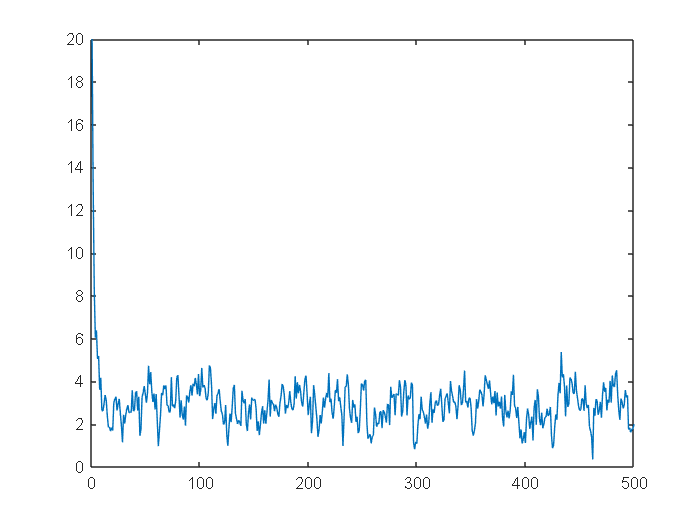

% EXERCISE 2 
% parameters
T=500;   % number of observations 
phi=.6;  % value of phi 
mu=3;    % unconditional expected value 
e=randn(T,1)*sqrt(.4); % white noise process 
y = zeros(T, 1); % Preallocate y to hold T observations
%starting condition
y(1)=20;

% using for
for t=2:T
    y(t)=mu+phi*(y(t-1)-mu)+e(t);
end

% plot 
plot(y)